% Kym Derriman (Partner: Evan Howell)
% Lab 6: Damped Harmonic Motion
% 10/17/2024

% -------------------------------------
% Spring Force vs Displacement Analysis
% -------------------------------------

% Background:

% k is the spring constant
% x is the displacement from equilibrium
% m is the mass added to spring
% g is the acceleration due to gravity

% rearrange Hooke's Law to solve for x:
%   x = mg/k

% we plotted displacement, x, on the y axis
% and m on the x axis and got a straight line
% because x is proportional to m.

% the general equation we use for the straight
% line is y = Bx + A

% In our case:
%   y corresponds x, the displacement;
%   x corresponds to m (mass);
%   B is the slope of the line;
%   A is the y intercept.

% So our equation becomes:
%   x = Bm + A

% The slope B represents how much the
% displacement x changes with added mass m.

% A represents the initial stretch of the spring.

% We relate the slope B to the spring constant k by:
%   x = mg/k
%   Bm + A = mg/k
%   Bm = mg/k - A
%   Ignoring A for the moment
%   B = g/k and k = g/B

% From lab we have B values.



% -----------------------------------------
% Import Measured Data weights = (0 - 100g)
% -----------------------------------------

% Preallocation and setup
num_measurements = 6;
position_means = zeros(1, num_measurements);
position_std_deviations = zeros(1, num_measurements);
position_std_err_mean = zeros(1, num_measurements);
filename.Temp = "S4L6_%d.txt";

% Loop to import and process data
for i = 1:num_measurements
    % Read data from corresponding file
    data = readtable(sprintf(filename.Temp, i));
    current_position = data.Position;
    N = length(current_position);
    position_means(i) = mean(current_position);
    position_std_deviations(i) = std(current_position);
    position_std_err_mean(i) = position_std_deviations(i)/sqrt(N);
end

% Convert position data to displacement by subtracting measured values
% of x - x_0. I did this because I was getting a negative slope (negative
% B value, which was giving me a complex number for my theoretical 
% calculation of period in step 12.

% Extract x_0 from position means
x0 = position_means(1);

% Calculate and create displacement array
displacement_array = x0 - position_means;

% Mass of weights in kg (from stamps on weights)
mass_weights = [0.0, 0.1, 0.2, 0.3, 0.4, 0.5];


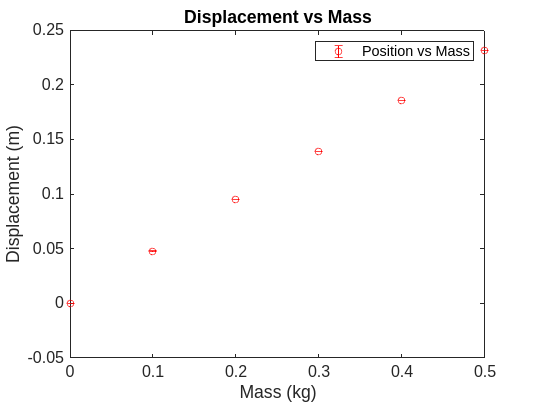


% -------------------------------
% Plot: Displacement vs. Mass
% -------------------------------

figure; grid on; box on;

% Plot Position with error bars
errorbar(mass_weights, displacement_array, position_std_err_mean, ...
    'ro', 'MarkerSize',5, 'DisplayName','Position vs Mass');

% Title and Labels with Uncertainties
title('Displacement vs Mass', 'FontSize', 14);
xlabel('Mass (kg)', 'FontSize', 11);
ylabel('Displacement (m)', 'FontSize', 11);
legend('Location','northeast');
set(gca, 'FontSize', 12);


% -----------------------------------
% Linear Fit for Spring Constant (k)
% -----------------------------------

% Performs a least-squares fit to the data, assuming a linear
% relationship between the mass of the weights and the
% displacement according to Hooke's Law (F = -k*x)

% A = y-intercept of the fit
% B = slope, related to spring constant k
% sigA and sigB are uncertainties in A, B
% weights = 1 / (std err mean)^2
[A, B, sigA, sigB] = lsqFit( ...
    mass_weights, ...
    displacement_array, ...
    1 ./((position_std_err_mean).^2));


Uncertainty in y-intercept (A): 0.0000


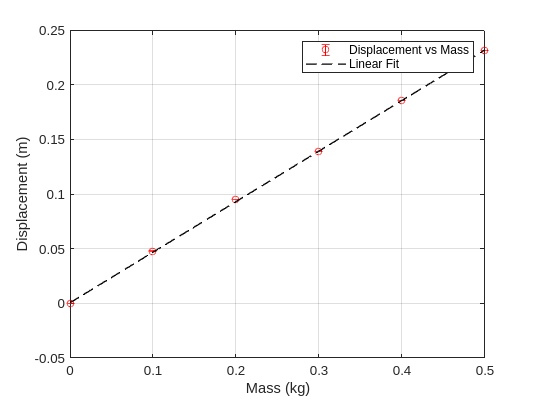

% Plot Linear Fit
figure; grid on; box on; hold on;

errorbar(mass_weights, displacement_array, position_std_err_mean, ...
    'ro', 'MarkerSize',5, 'DisplayName','Position vs Mass');

x_fit = linspace(min(mass_weights), max(mass_weights), 100);
y_fit = B * x_fit + A;
plot(x_fit, y_fit, 'k--', 'LineWidth', 1)
xlabel('Mass (kg)', 'FontSize', 11);
ylabel('Displacement (m)', 'FontSize', 11);

% Legend to show both the data and the fit
legend({'Displacement vs Mass', 'Linear Fit'}, 'Location', 'northeast');

% Set x-axis limits to only plot the data within the range
xlim([min(mass_weights), max(mass_weights)]);


fprintf('Uncertainty in y-intercept (A): %.4f\n', sigA);

% -----------------------------------
% Calculation of Spring Constant (k)
% -----------------------------------

% This computes the fitted line (position vs mass) using the 
% linear fit equation: Position = A + B * mass_weights

position = A + B.*mass_weights;

% The slope B from the linear fit is related to the spring
% constant k by the equation: k = g/B, where g is gravity

g = 9.8;
k = g/B;

% Uncertainty in k (sigK) is calculated from uncertainty in B
% using error propagation (derivative of k to B times sigma B)
sigK = ((g)/((B)^2))*sigB;

% Print results of measured spring constant.
fprintf('Measured Spring Constant and Uncertainty:\n');

Measured Spring Constant and Uncertainty:


fprintf('-------------------------------------------\n');

-------------------------------------------


fprintf('Spring Constant (k) = %.2f\n', k);

Spring Constant (k) = 21.18


fprintf('Uncertainty in Spring Constant (k) = %.2f', sigK);

Uncertainty in Spring Constant (k) = 0.00

fprintf('-------------------------------------------\n');

-------------------------------------------


% -----------------------------------------
% Import Measured Data weight = 500g
% -----------------------------------------

% For this section, we measured observations of an
% oscillating spring with 500g weight attached.

tbl = readtable("L6_500g_Oscillation.txt");
times = tbl.Time;
positions = tbl.Position;
velocities = tbl.Velocity;
accelerations = tbl.Acceleration;


% -----------------------------------------
% Data Preparation
% -----------------------------------------

% We need to prepare our data to plot it so that
% the motion oscillates about zero.

% Calculate the means 
position_means = mean(positions);
vel_means = mean(velocities);
accel_means = mean(accelerations);

% Shift each plot down by subtracting means from
% measured values.
shifted_positions = positions - position_means;
shifted_velocities = velocities - vel_means;
shifted_accelerations = accelerations - accel_means;

% Convert position data to displacement data
x0 = shifted_positions(1);
shifted_displacements = x0 - shifted_positions;

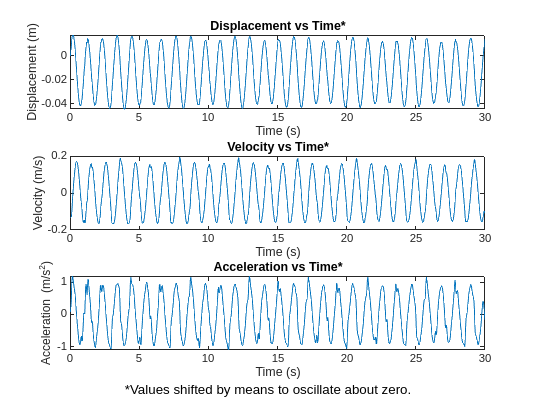

% --------------------------------------------------
% Plot Position, Velocity, Acceleration Data
% --------------------------------------------------

figure;

% Subplot 1: Positions (shifted)
subplot(3, 1, 1);
plot(times, shifted_displacements);
title('Displacement vs Time*');
xlabel('Time (s)');
ylabel('Displacement (m)');

% Subplot 2: Velocities (shifted)
subplot(3, 1, 2);
plot(times, shifted_velocities);
title('Velocity vs Time*');
xlabel('Time (s)');
ylabel('Velocity (m/s)');

% Subplot 3: Accelerations (shifted)
subplot(3, 1, 3);
plot(times, shifted_accelerations);
title('Acceleration vs Time*');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

% Add annotation to indicate the asterisk explanation
annotation('textbox', [0.1, 0.01, 0.8, 0.05], 'String', ...
    '*Values shifted by means to oscillate about zero.','EdgeColor', 'none', ...
    'HorizontalAlignment', 'center', 'FontSize', 10);

Uncertainty in y-intercept (A): 1.4703


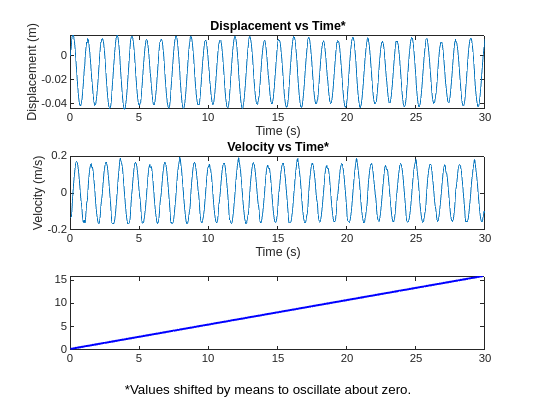

% --------------------------------------------------
% Find the Times When Position Closest to Zero
% --------------------------------------------------

% Examine data and find threshold value that is bigger than zero
% but smaller than next number.

% Threshold value
trs = 0.0023;

% Check if the absolute value of the position is less than the
% threshold, which would indicate a zero crossing.
zero_crossings = times(abs(shifted_displacements) < trs);

% Setting weights for the fit, this gives each zero crossing an
% equal contribution of 1/30 to the least-squares fit.
w = ones(length(zero_crossings), 1)*(1/30);

% Least-squares fit:
%   A is the y intercept, the time of first zero crossing
%   B is the interval between two zero crossings
%   sigma A 
%   which is equal to half of a period.
[A, B, sigA, sigB] = lsqFit(1:length(zero_crossings), zero_crossings, w);


% --------------------------------------------------
% Extract T of Position and Compare Against Theory
% --------------------------------------------------

% Extract value of T, the period of oscillation:
% B is one half period, so T = 2 * B, and similarly the uncertainty
% of T is twice that of the uncertainty of B.
T_measured = 2 * B;
sigT = 2 * sigB;

% To calculate theoretical value of T, we need the mass of the weight,
% the mass of the weight holder, and the effective mass of the spring.

% Mass of weight holder
mass_holder = 99.1/1000; % grams to kg

% Effective mass of spring (1/3 * spring mass)
mass_spring_eff = 29.2/1000; % grams to kg

% Mass of weight
mass_weight = 500/1000; % g to kg

% Total mass for theoretical T calculation
total_mass = mass_holder + mass_spring_eff + mass_weight;

% Calculate theoretical value of T with T = 2*pi*sqrt(m/k) where m is
% the mass of the weight, the weight holder and the spring weight.
T_theoretical = 2*pi*sqrt(total_mass/k);

% Print results of T measured vs T theoretical for comparison.
fprintf('Comparison of Measured and Theoretical Period T (Position Data):\n');

Comparison of Measured and Theoretical Period T (Position Data):


fprintf('-----------------------------------------------------------------\n');

-----------------------------------------------------------------


fprintf('Measured period (T_measured): %.4f s\n', T_measured);

Measured period (T_measured): 1.0475 s


fprintf('Uncertainty in measured period (sigT): %.4f s\n', sigT);

Uncertainty in measured period (sigT): 0.0882 s


fprintf('Theoretical period (T_theoretical): %.4f s\n', T_theoretical);

Theoretical period (T_theoretical): 1.0821 s


fprintf('-----------------------------------------------------------------\n');

-----------------------------------------------------------------



% Print masses for clarity
fprintf('Mass of weight (kg): %.4f kg\n', mass_weight);

Mass of weight (kg): 0.5000 kg


fprintf('Mass of weight holder (kg): %.4f kg\n', mass_holder);

Mass of weight holder (kg): 0.0991 kg


fprintf('Effective mass of spring (kg): %.4f kg\n', mass_spring_eff);

Effective mass of spring (kg): 0.0292 kg


fprintf('Total mass used in theoretical calculation (kg): %.4f kg\n', total_mass);

Total mass used in theoretical calculation (kg): 0.6283 kg


% --------------------------------------------------
% Find the Times When Velocity is Closest to Zero
% --------------------------------------------------

% Examine data and find threshold value that is bigger than zero
% but smaller than next number.

% Threshold value
trs = 0.0017;

% Check if the absolute value of the position is less than the
% threshold, which would indicate a zero crossing.
zero_crossings = times(abs(shifted_velocities) < trs);

% Setting weights for the fit, this gives each zero crossing an
% equal contribution of 1/30 to the least-squares fit.
w = ones(length(zero_crossings), 1)*(1/30);

% Least-squares fit:
%   A is the y intercept, the time of first zero crossing
%   B is the interval between two zero crossings
%   sigma A 
%   which is equal to half of a period.
[A, B, sigA, sigB] = lsqFit(1:length(zero_crossings), zero_crossings, w);
fprintf('Uncertainty in y-intercept (A): %.4f\n', sigA);

Uncertainty in y-intercept (A): 5.7446


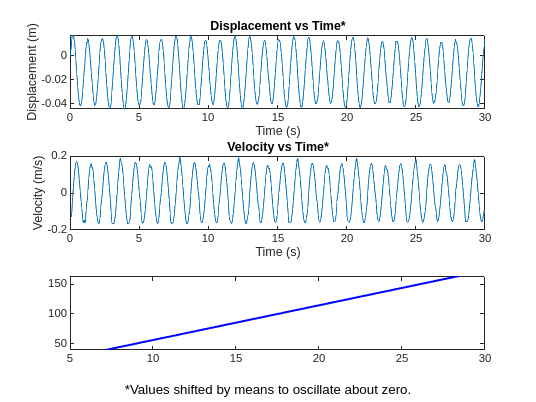


% This calculates the linear fit line based on the values of A and
% B. It computes the fitted values at each zero crossing.
periodLSF = A + B.*zero_crossings;
plot(zero_crossings, periodLSF, 'b-', 'LineWidth', 1.5);

% --------------------------------------------------
% Extract T of Velocity and Compare Against Theory
% --------------------------------------------------

% Extract value of T, the period of oscillation:
% B is one half period, so T = 2 * B, and similarly the uncertainty
% of T is twice that of the uncertainty of B.
T_measured = 2 * B;
sigT = 2 * sigB;

% Calculate theoretical value of T with T = sqrt(2pi*m/k) where m is
% the mass of the weight, the weight holder and the spring weight.
T_theoretical = 2*pi*sqrt(total_mass/k);

% Print results of T measured vs T theoretical for comparison.
fprintf('Comparison of Measured and Theoretical Period T (Velocity Data):\n');

Comparison of Measured and Theoretical Period T (Velocity Data):


fprintf('-----------------------------------------------------------------\n');

-----------------------------------------------------------------


fprintf('Measured period (T_measured): %.4f s\n', T_measured);

Measured period (T_measured): 11.7132 s


fprintf('Uncertainty in measured period (sigT): %.4f s\n', sigT);

Uncertainty in measured period (sigT): 3.4641 s


fprintf('Theoretical period (T_theoretical): %.4f s\n', T_theoretical);

Theoretical period (T_theoretical): 1.0821 s


fprintf('-----------------------------------------------------------------\n');

-----------------------------------------------------------------


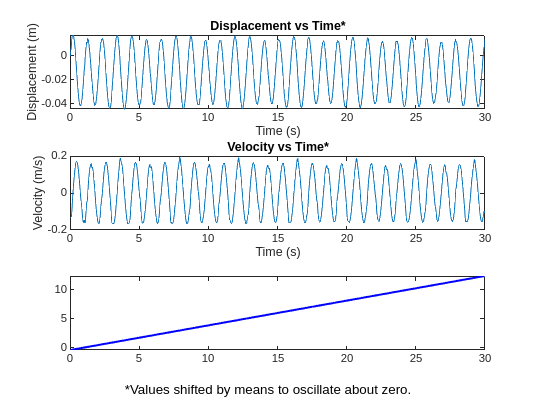

% ----------------------------------------------------
% Find the Times When Acceleration is Closest to Zero
% ----------------------------------------------------

% Examine data and find threshold value that is bigger than zero
% but smaller than next number.

% Threshold value
trs = 0.12;

% Check if the absolute value of the position is less than the
% threshold, which would indicate a zero crossing.
zero_crossings = times(abs(shifted_accelerations) < trs);

% Setting weights for the fit, this gives each zero crossing an
% equal contribution of 1/30 to the least-squares fit.
w = ones(length(zero_crossings), 1)*(1/30);

% Least-squares fit:
%   A is the y intercept, the time of first zero crossing
%   B is the interval between two zero crossings
%   sigma A 
%   which is equal to half of a period.
[A, B, sigA, sigB] = lsqFit(1:length(zero_crossings), zero_crossings, w);

% This calculates the linear fit line based on the values of A and
% B. It computes the fitted values at each zero crossing.
periodLSF = A + B.*zero_crossings;
plot(zero_crossings, periodLSF, 'b-', 'LineWidth', 1.5);

% --------------------------------------------------
% Extract T of Acceleration and Compare Against Theory
% --------------------------------------------------

% Extract value of T, the period of oscillation:
% B is one half period, so T = 2 * B, and similarly the uncertainty
% of T is twice that of the uncertainty of B.
T_measured = 2 * B;
sigT = 2 * sigB;

% Calculate theoretical value of T with T = sqrt(2pi*m/k) where m is
% the mass of the weight, the weight holder and the spring weight.
T_theoretical = 2*pi*sqrt(total_mass/k);

% Print results of T measured vs T theoretical for comparison.
fprintf('Comparison of Measured and Theoretical Period T (Acceleration Data):\n');

Comparison of Measured and Theoretical Period T (Acceleration Data):


fprintf('---------------------------------------------------------------------\n');

---------------------------------------------------------------------


fprintf('Measured period (T_measured): %.4f s\n', T_measured);

Measured period (T_measured): 0.8537 s


fprintf('Uncertainty in measured period (sigT): %.4f s\n', sigT);

Uncertainty in measured period (sigT): 0.0634 s


fprintf('Theoretical period (T_theoretical): %.4f s\n', T_theoretical);

Theoretical period (T_theoretical): 1.0821 s


fprintf('---------------------------------------------------------------------\n');

---------------------------------------------------------------------











%-----------------------------------------------------

